clc;
clear;
close all;

%% SIMULATION PARAMETERS
T = 5;                  % total time (seconds)
dt = 0.01;
time = 0:dt:T;

%% PACKET RATES (packets/sec)
icmp_rate = 5;          % low rate (ping)
tcp_rate = 50;          % medium rate
http_rate = 20;         % bursty

%% INITIALIZATION
icmp_packets = zeros(size(time));
tcp_packets = zeros(size(time));
http_packets = zeros(size(time));

%% GENERATE TRAFFIC

for i = 1:length(time)
    
    % ICMP (simple periodic ping-like)
    if mod(i, round(1/(icmp_rate*dt))) == 0
        icmp_packets(i) = 1;
    end
    
    % TCP (continuous random traffic)
    if rand < tcp_rate*dt
        tcp_packets(i) = 1;
    end
    
    % HTTP (bursty traffic)
    if rand < http_rate*dt
        burst_size = randi([1 5]); % multiple packets
        http_packets(i:min(i+burst_size,length(time))) = 1;
    end
end

%% PACKET SIZES (bytes)
icmp_size = 64;      % small
tcp_size = 512;      % medium
http_size = 1500;    % large

%% TRAFFIC CALCULATION

icmp_traffic = icmp_packets * icmp_size;
tcp_traffic = tcp_packets * tcp_size;
http_traffic = http_packets * http_size;

total_traffic = icmp_traffic + tcp_traffic + http_traffic;

%% STATISTICS

fprintf('ICMP Packets: %d\n', sum(icmp_packets));

ICMP Packets: 25


fprintf('TCP Packets: %d\n', sum(tcp_packets));

TCP Packets: 261


fprintf('HTTP Packets: %d\n', sum(http_packets));

HTTP Packets: 300



fprintf('Total Traffic (bytes): %.0f\n', sum(total_traffic));

Total Traffic (bytes): 585232


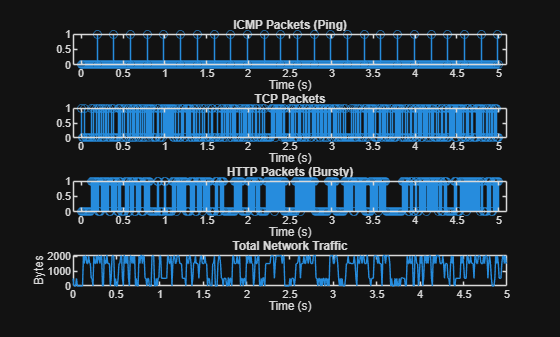


%% PLOTS

figure;

subplot(4,1,1);
stem(time, icmp_packets);
title('ICMP Packets (Ping)');
xlabel('Time (s)');

subplot(4,1,2);
stem(time, tcp_packets);
title('TCP Packets');
xlabel('Time (s)');

subplot(4,1,3);
stem(time, http_packets);
title('HTTP Packets (Bursty)');
xlabel('Time (s)');

subplot(4,1,4);
plot(time, total_traffic);
title('Total Network Traffic');
xlabel('Time (s)');
ylabel('Bytes');